# 绘图修饰

（线型、线宽、颜色、描点类型、网格、坐标轴刻度）

### 1、线型

-实线  --虚线  :点线  -.点画线

### 2、描点类型

.点  o圆  x叉号  +加号  *星号

< > ^ v三角形

s方形  d菱形  p五角星  h六角星

### 3、颜色

r红色

g绿色

b深蓝

y黄色

w白色

k黑色

% plot(x, y, '- r o', ...     % 线型直线、颜色red、描点类型（顺序可变）
%            'lineWidth', 1, ...           % 线宽
%            'MarkerEdgeColor', 'r', ...   %描点边框颜色
%            'MarkerFaceColor', 'y', ...   %描点内部填充颜色
%            'MarkerSize', 10)         %描点大小

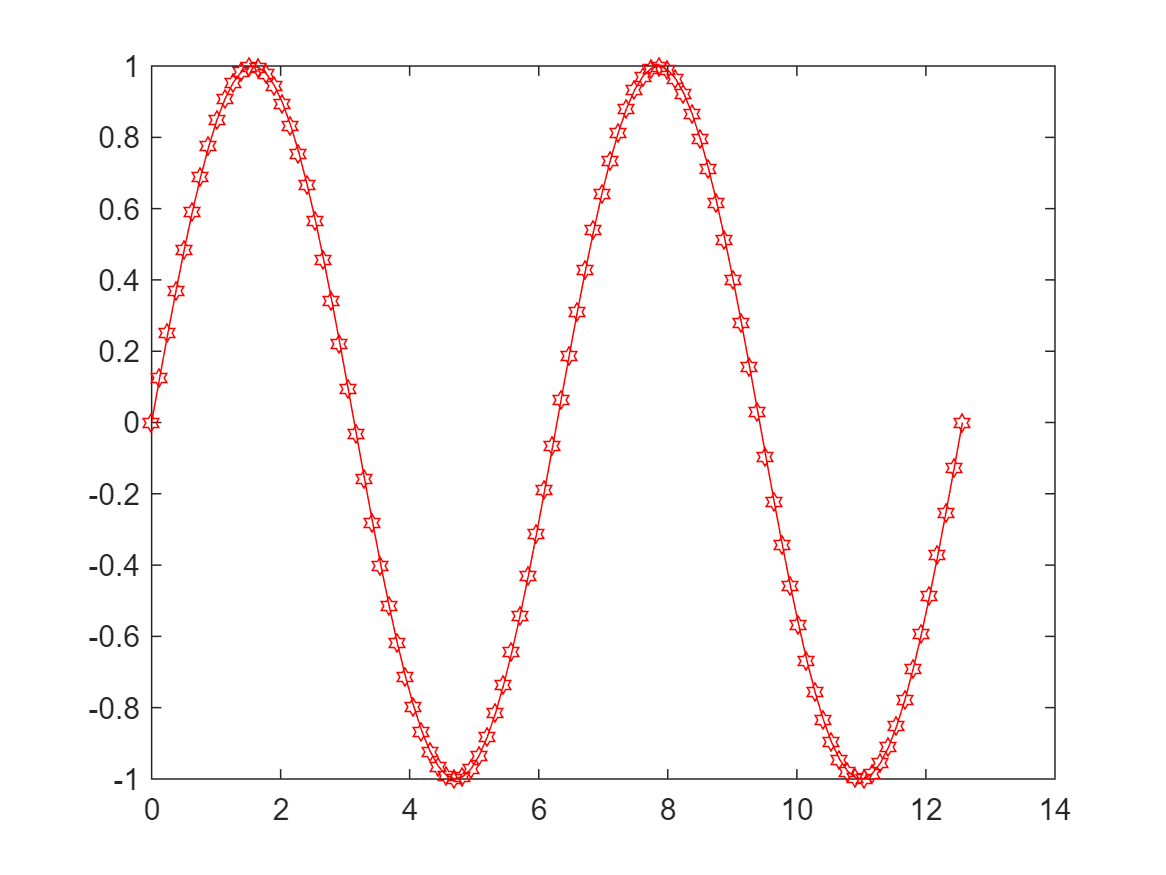

x = linspace(0, 4*pi, 100);
y1 = sin(x);
y2 = cos(x);
y3 = x.^2;

plot(x, y1, 'r h -');

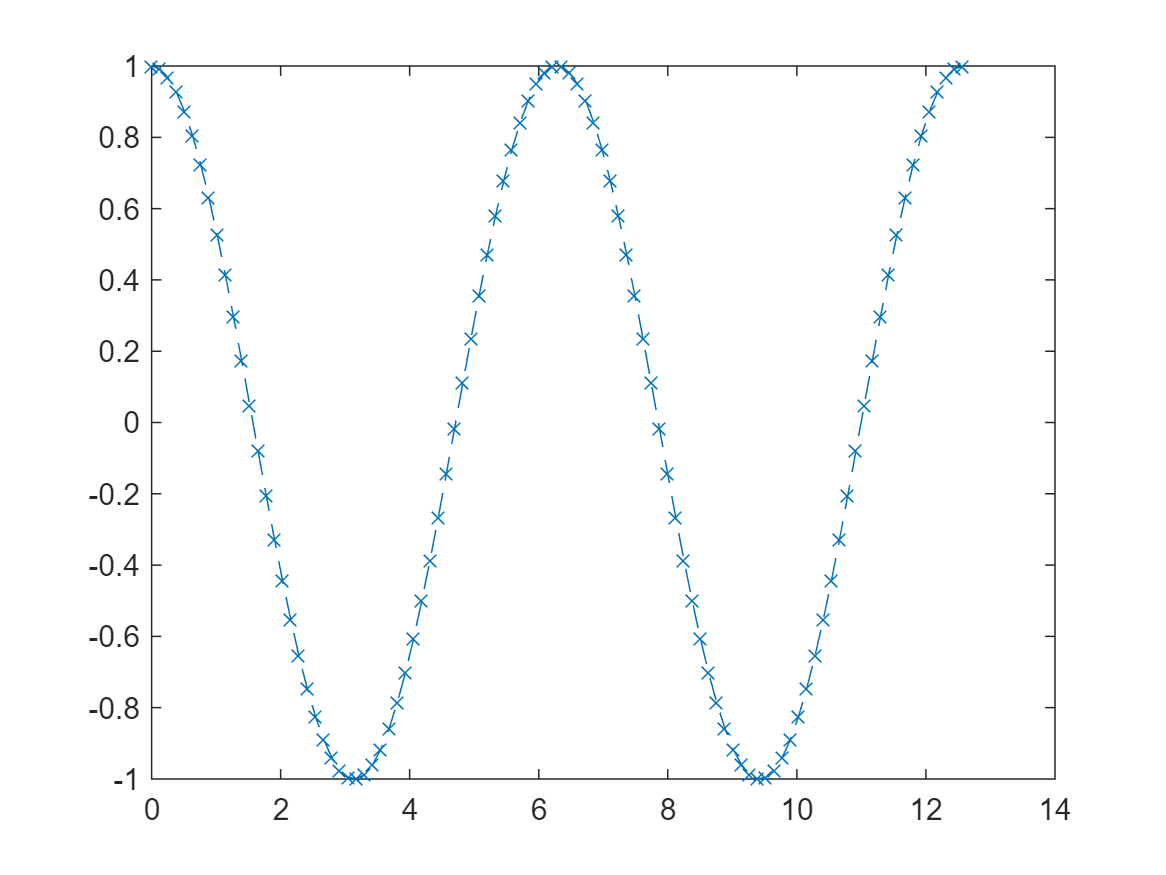

plot(x, y2, '-- x')

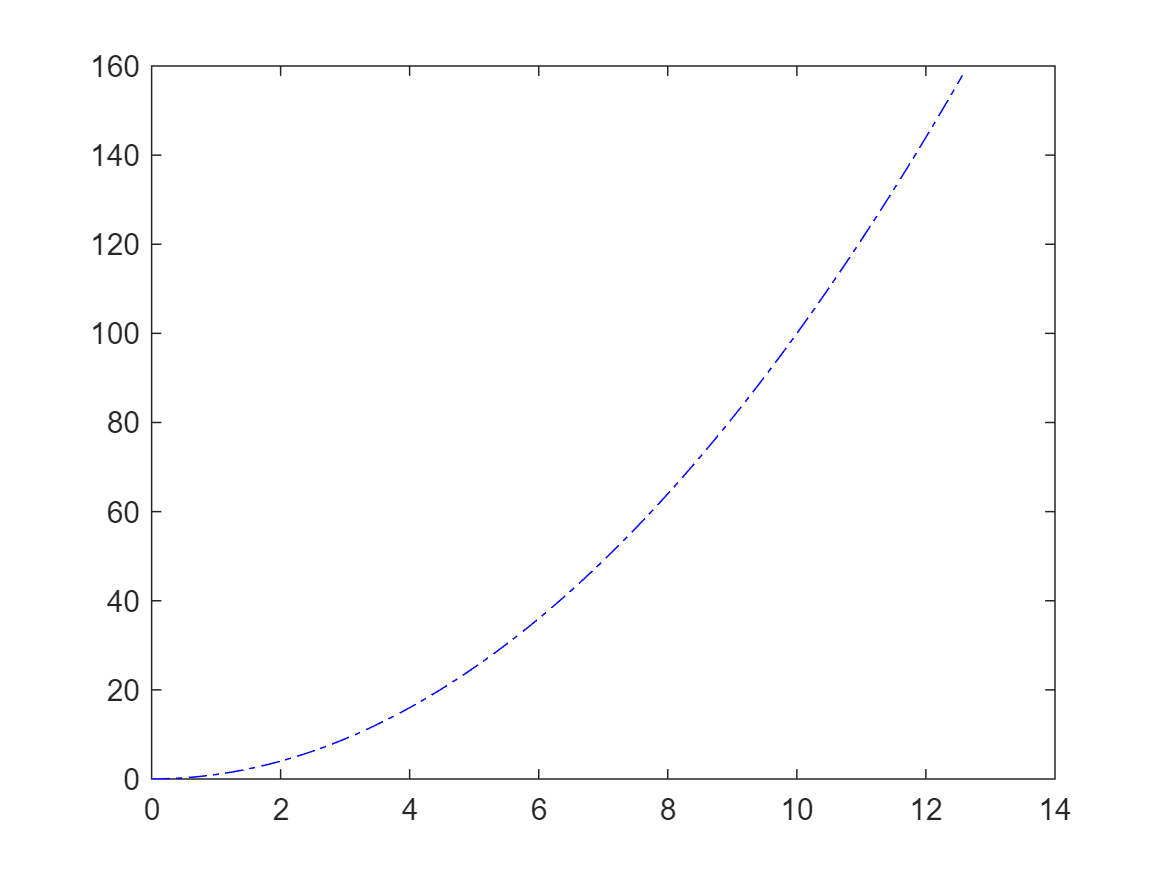

plot(x, y3, '-. b')

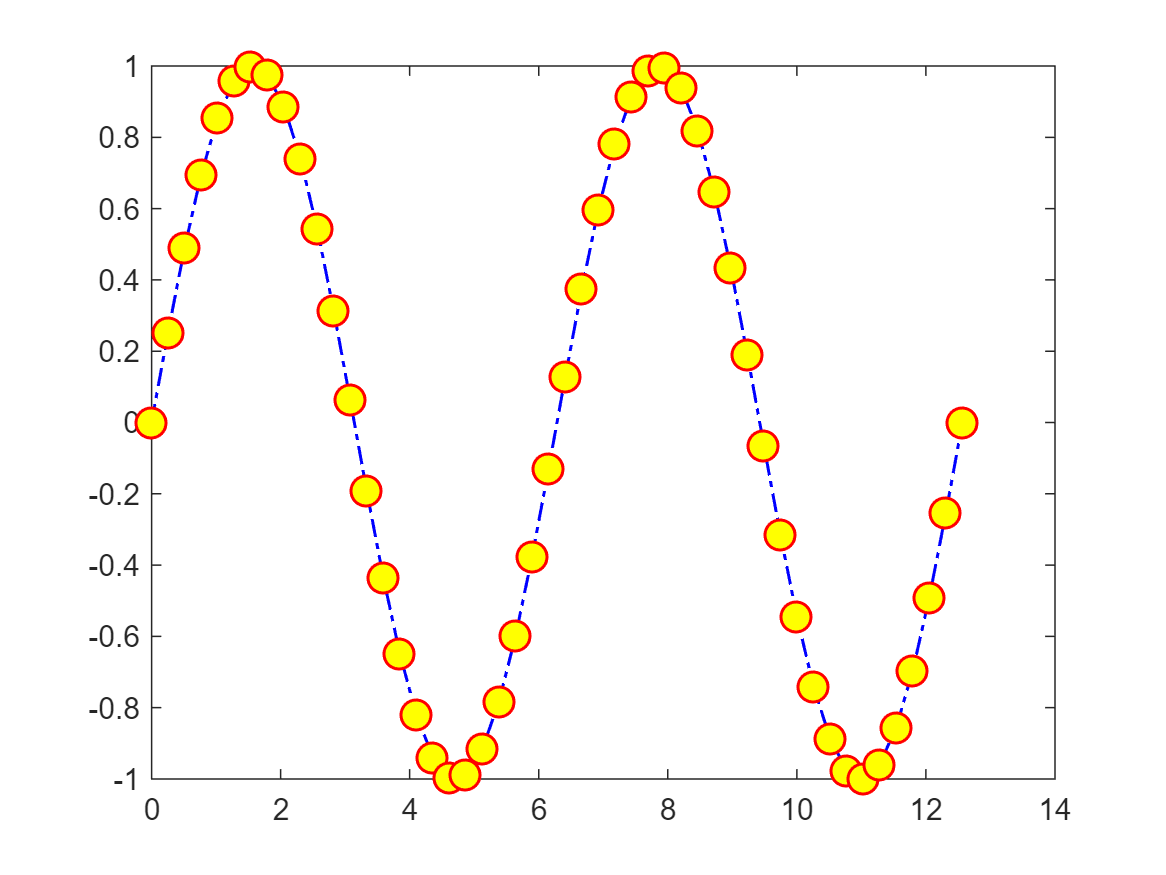

x = linspace(0, 4*pi, 50);
y1 = sin(x);
y2 = cos(x);
y3 = x.^2;

plot(x, y1, '-. b o', ...
            'lineWidth', 1, ...           % 线宽
           'MarkerEdgeColor', 'r', ...   %描点边框颜色
           'MarkerFaceColor', 'y', ...   %描点内部填充颜色
           'MarkerSize', 10)

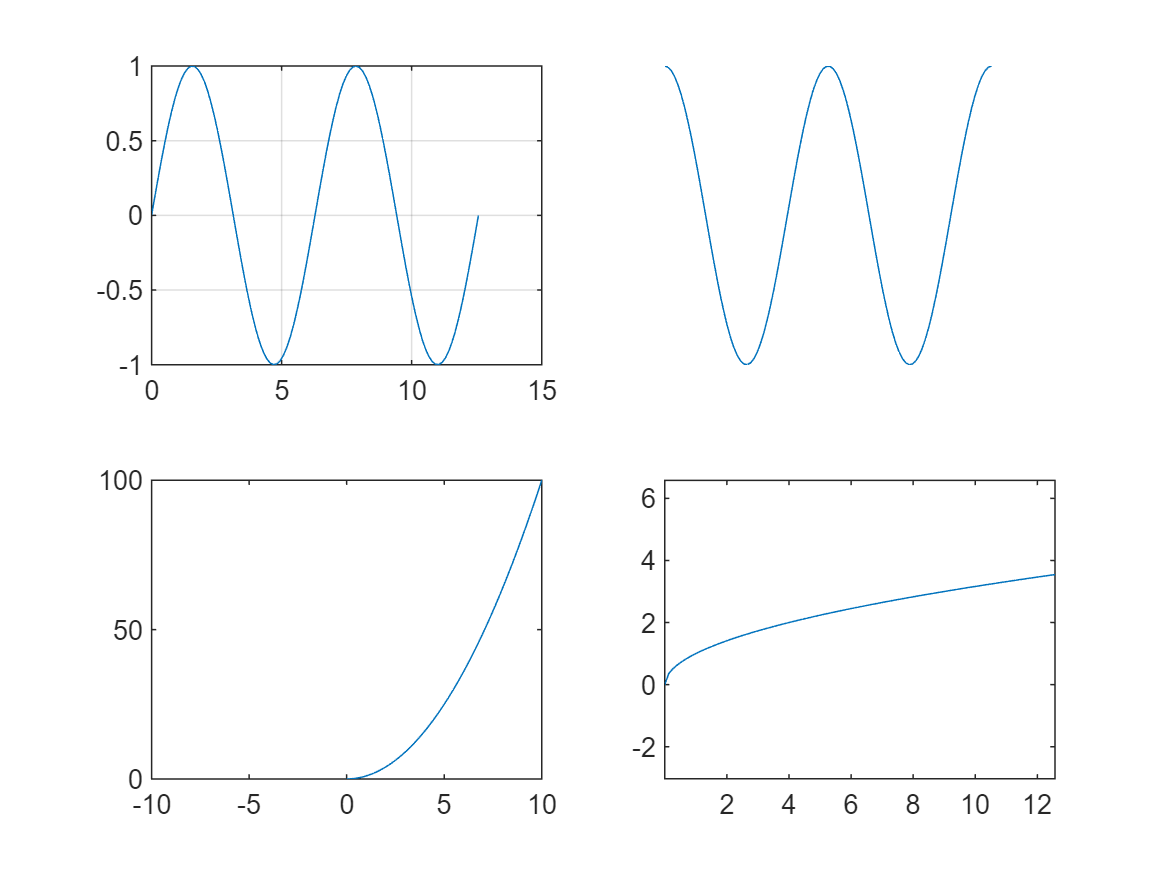

% grid on                           %添加网格
% grid off                          %取消网格

% axis on                           %显示坐标轴、刻度线和坐标轴标签
% axis off                          %关闭坐标轴、刻度线和坐标轴标签
% axis([xmin, xmax, ymin, ymax])    %设置x轴、y轴显示范围
% axis equal                        %沿每个坐标轴使用相同的数据单位长度
% axis square                       %使用相同长度的坐标轴线，相应调整数据单位之间的增量


x = linspace(0, 4*pi, 100);
y1 = sin(x);
y2 = cos(x);
y3 = x.^2;
y4 = x.^0.5;

subplot(2, 2, 1); plot(x, y1); grid on;
subplot(2, 2, 2); plot(x, y2); axis off;
subplot(2, 2, 3); plot(x, y3); axis([-10, 10, 0, 100]);
subplot(2, 2, 4); plot(x, y4); axis equal;